clear;
sanboks_data = xlsread('Spreadsheets\Formula_Bharat\Sanboks_Data_Autocross.xlsx');
[g, h] = size(sanboks_data);
track = sanboks_data(24:g,12:13);
track=rmmissing(track);
motor = sanboks_data(24:g,3:9);
gear_ratio =sanboks_data(9,9) ;
tire_radius = sanboks_data(7,4);
final_drivetrain_efficiency = sanboks_data(10,9);
car_mass = sanboks_data(1,4);
rot_mass = sanboks_data(2,4);
rot_mass = rmmissing(rot_mass);
coefficient_rolling_resistance = sanboks_data(8,4);
frontal_area = sanboks_data(7,13);
drag_coefficient = sanboks_data(9,13);
lift_coefficient = sanboks_data(8,13);
aero_balance = sanboks_data(10,13);
grade_of_track = 0;
no_of_motors = sanboks_data(7,9);
supply_voltage = sanboks_data(11,9);
min_radius=sanboks_data(16,9);
front_braking_torque = sanboks_data(16,4);
Rear_braking_torque = sanboks_data(17,4);
no_laps=sanboks_data(1,13);
start_time_for_peak=sanboks_data(8,9);
x= track(:,1)/1000;
y= track(:,2)/1000;
long_friction = sanboks_data(9,4);
lat_friction = sanboks_data(10,4);
rear_weight_distribution = sanboks_data(1,9);
steering_ratio = sanboks_data(16,13);
wheelbase =	sanboks_data(7,17); %wheelbase mm
center_of_gravity= sanboks_data(8,17); %Height CG mm
front_trackwidth= sanboks_data(9,17); %(Front Track Width) mm
rear_trackwidth= sanboks_data(10,17); %(Rear Track Width) mm
hr=	sanboks_data(11,17); %(roll centre height rear axle) mm
hf=	sanboks_data(12,17); %(Roll center height front axle) mm 
h1r= sanboks_data(13,17); %(C.G. above roll axis) mm
h1f = sanboks_data(14,17); %(C.G. above roll axis) mm 
h1=	sanboks_data(15,17); %(C.G. above roll axis) mm
rear_frequency = sanboks_data(16,17);  %Hz
front_frequency = sanboks_data(17,17); %Hz
rear_tire_rate = sanboks_data(18,17);  %Nmm
front_tire_rate = sanboks_data(19,17); %Nmm
rear_motion_ratio = sanboks_data(20,17);
front_motion_ratio  = sanboks_data(21,17);
plot(x,y);
x_leng=length(x);
for j=1:no_laps-1
    for i=1:x_leng
        x((j)*x_leng+i)=x(i);
        y((j)*x_leng+i)=y(i);
    end
end

Motor data extraction

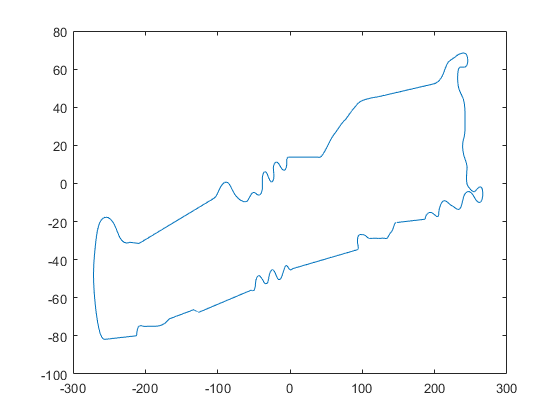

air_density = 1.12;
gravity = 9.81;
%%
peak_rpm = motor(:,4);
peak_torque = motor(:,3);
conti_rpm = motor(:,7);
conti_torque = motor(:,6);
current = motor(:,1);

%%
%removing the NaN from the data.
peak_rpm = rmmissing(peak_rpm);
peak_torque = rmmissing(peak_torque);
conti_rpm = rmmissing(conti_rpm);
conti_torque = rmmissing(conti_torque);
current = rmmissing(current);
%%
% PID value
peak_PID_increment = 1/(length(peak_rpm)-1);
conti_PID_increment = 1/(length(conti_rpm)-1);
peak_PID = 0:peak_PID_increment:1;
conti_PID = 0:conti_PID_increment:1;

%%